**Параметры системы компенсирующий регулятор**

A1 = [1, 2, 0;
    0, 1, 3;
    1, -5, 1];
A2 = [0, 2, 0, 0;
    -2, 0, 0, 0;
    0, 0, 0, 1;
    0, 0, -1, 0];
B1 = [0; 2; 2];
B2 = [1, 0, 0, 0;
    0, 4, 0, 0;
    0, 0, 8, 0];
C2 = [0, 1, 0];
D2 = [0, 0, 0, 0];

x0 = [1; 2; 3];
w0 = [0; -2; -3; 1];

Проверка собственных чисел

disp(eig(A1));

   1.3959 + 0.0000i
   0.8021 + 3.8881i
   0.8021 - 3.8881i



disp(eig(A2));

   0.0000 + 2.0000i
   0.0000 - 2.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i



Управляемость A1 и В1

U = ctrb(A1,B1);
rank(U);

**Вычисление LQR регулятора**

Матрицы Q и R 

Q = eye(3);
R = 1;

Вычисление матрицы регулятора K1 LQR регулятор

[P, ~, ~] = icare(A1, B1, Q, R, [], [], [], []);
K1 = -inv(R) * B1' * P

K1 =    -5.2013   -3.0678   -1.3310


Вычисление матрицы K2 регулятора

cvx_begin sdp quiet;
variables P(length(A1),length(A2)) Y(1,length(A2))
P*A2 - A1*P == B1*Y + B2;
C2*P == 0;
cvx_end;
K2 = Y - K1*P

K2 =    -0.8459   -3.9031   -0.5407    0.2704


Проверка системы на соответствие условий (принадлежности собств чисел А1 не в  С_, А2 к С+б A1+BK в С_)

disp(eig(A1 + B1*K1))

  -2.1855 + 3.9108i
  -2.1855 - 3.9108i
  -1.4268 + 0.0000i



Построение графиков

plot(out.z.Time, out.z.Data, LineWidth=2.0);

Unrecognized field name "z".

hold on;
plot(out.z1.Time, out.z1.Data, LineWidth=2.0, LineStyle="--");
title('Controler compare','Interpreter', 'latex', 'FontSize', 16);
xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
legend('Feedback and feedforward', 'Feedback LQR', 'Interpreter', 'latex', 'FontSize', 15);
grid on;

% hold off;
% 
% plot(out.x.Time, out.x.Data(:, 2), LineWidth=2.0);
% hold on;
% plot(out.x1.Time, out.x1.Data(:, 2), LineWidth=2.0, LineStyle="--");
% title('Controler compare for $x_{2}(t)$','Interpreter', 'latex', 'FontSize', 16);
% xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
% ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
% legend('Feedback and feedforward', 'Feedback LQR', 'Interpreter', 'latex', 'FontSize', 15);
% grid on;

hold off;

plot(out.x.Time, out.x.Data, LineWidth=2.0);
hold on;
title('$x_{FF}(t)$','Interpreter', 'latex', 'FontSize', 16);
xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
legend('$x_{1}(t)$', '$x_{2}(t)$','$x_{3}(t)$', 'Interpreter', 'latex', 'FontSize', 15);
grid on;

hold off;

plot(out.x1.Time, out.x1.Data, LineWidth=2.0);
hold on;
title('$x_{F}(t)$','Interpreter', 'latex', 'FontSize', 16);
xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
legend('$x_{1}(t)$', '$x_{2}(t)$','$x_{3}(t)$', 'Interpreter', 'latex', 'FontSize', 15);
grid on;

**Следящий регулятор данные**

D2 = [1,2,3,4];
B2 = [0, 0, 0, 0;
    0, 0, 0, 0;
    0, 0, 0, 0];

Вычисление матрицы K2 регулятора

cvx_begin sdp quiet;
variables P(length(A1),length(A2)) Y(1,length(A2))
P*A2 - A1*P == B1*Y;
C2*P + D2 == 0;
cvx_end;
K2 = Y - K1*P

K2 =    -7.6712    2.0682  -13.2705   23.4551


Построение графиков

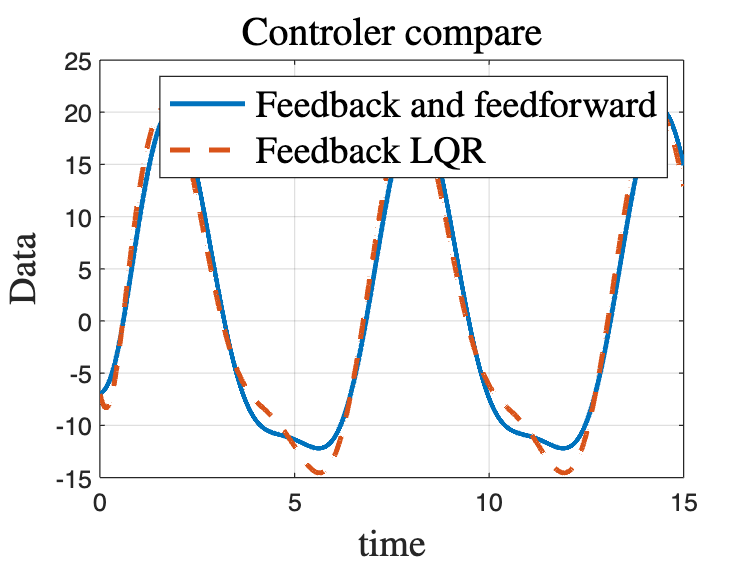

hold off;

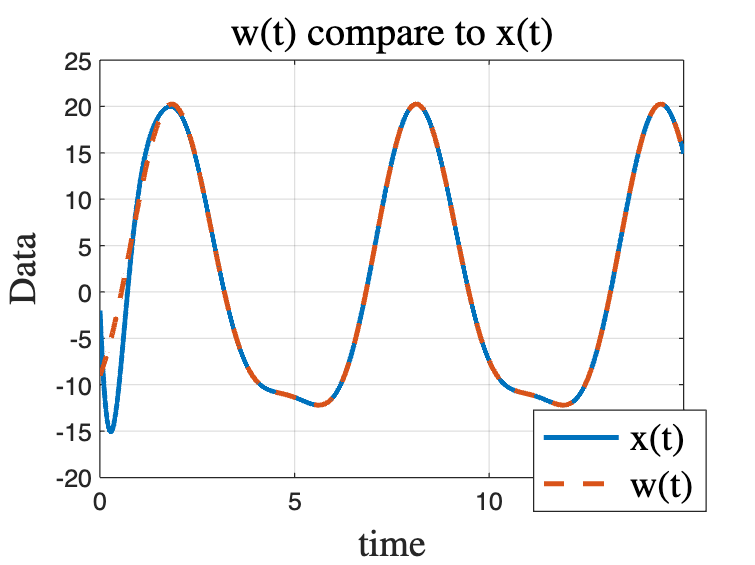


plot(out.xx.Time, -1*out.xx.Data, LineWidth=2.0);
hold on;
plot(out.ww.Time, out.ww.Data, LineWidth=2.0, LineStyle="--");
title('w(t) compare to x(t)','Interpreter', 'latex', 'FontSize', 16);
xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
legend('x(t)', 'w(t)', 'Interpreter', 'latex', 'FontSize', 15);
grid on;

hold off;

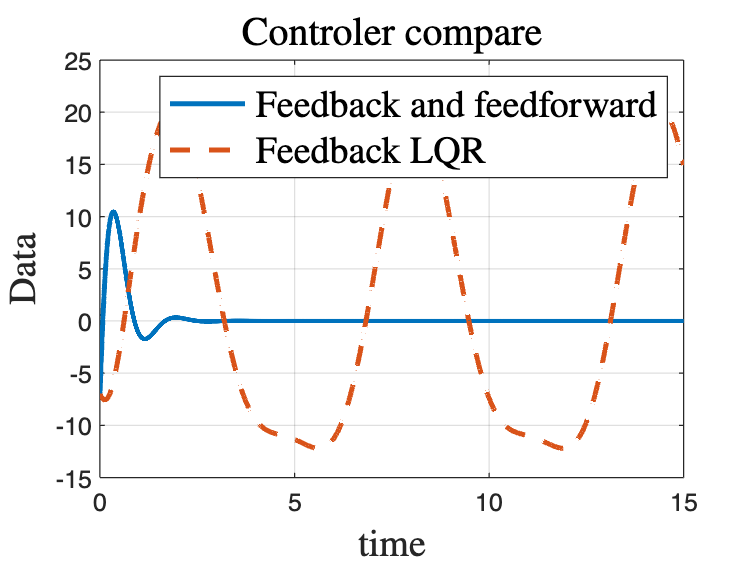


plot(out.z.Time, out.z.Data, LineWidth=2.0);
hold on;
plot(out.z1.Time, out.z1.Data, LineWidth=2.0, LineStyle="--");
title('Controler compare','Interpreter', 'latex', 'FontSize', 16);
xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
legend('Feedback and feedforward', 'Feedback LQR', 'Interpreter', 'latex', 'FontSize', 15);
grid on;